close all;
clear variables;
clc;

folder = "CUB_200_2011_Subset20classes";
trainingImageNames = readtable(fullfile(folder, "train.txt"),'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(fullfile(folder, "validate.txt"),'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(fullfile(folder, "test.txt"),'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

classNames = readtable(fullfile(folder, "classes.txt"),'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(fullfile(folder, "image_class_labels.txt"),'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

folder = "CUB_200_2011_Subset20classes/";
trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;

validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;

testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;

countEachLabel(trainingImageDS)

countEachLabel(validationImageDS)

countEachLabel(testImageDS)

% target_size = [100, 100];
target_size = [224, 224];

% resizing using transform operation
training_image_datastore_resized = transform(trainingImageDS, @(image_i) imresize(image_i,target_size));
validation_image_datastore_resized = transform(validationImageDS, @(image_i) imresize(image_i,target_size));
test_image_datastore_resized = transform(testImageDS, @(image_i) imresize(image_i,target_size));

% Combine transformed datastores and labels
training_labels = arrayDatastore(trainingImageDS.Labels);
training_combined_datastore = combine(training_image_datastore_resized, training_labels);

validation_labels = arrayDatastore(validationImageDS.Labels);
validation_combined_datastore = combine(validation_image_datastore_resized, validation_labels);

test_labels = arrayDatastore(testImageDS.Labels);
test_combined_datastore = combine(test_image_datastore_resized, test_labels);


% cnn architecture 
number_of_layers = 6;

layers = [
    imageInputLayer([224 224 3])
    
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 256, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)

    % Fully connected block
    fullyConnectedLayer(512)
    batchNormalizationLayer
    reluLayer
    dropoutLayer(0.5)
    
    fullyConnectedLayer(256)
    batchNormalizationLayer
    reluLayer
    dropoutLayer(0.5)
    
    fullyConnectedLayer(20)
    softmaxLayer
    classificationLayer];


if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    gpu_device = gpuDevice(1);
    reset(gpu_device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index        Name        ComputeCapability    DeviceAvailable    DeviceSelected
    _____    ____________    _________________    _______________    ______________

      1      "GRID T4-8Q"          "7.5"               true              true      



Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |        6.25% |        5.41% |       4.1432 |       3.3965 |          0.0010 |
|       1 |           2 |       00:00:15 |        6.25% |              |       4.1879 |              |          0.0010 |
|       1 |           3 |       00:00:16 |        6.25% |              |       4.5379 |              |          0.0010 |
|       1 |           4 |       00:00:16 |        0.00% |              |       4.1687 |   

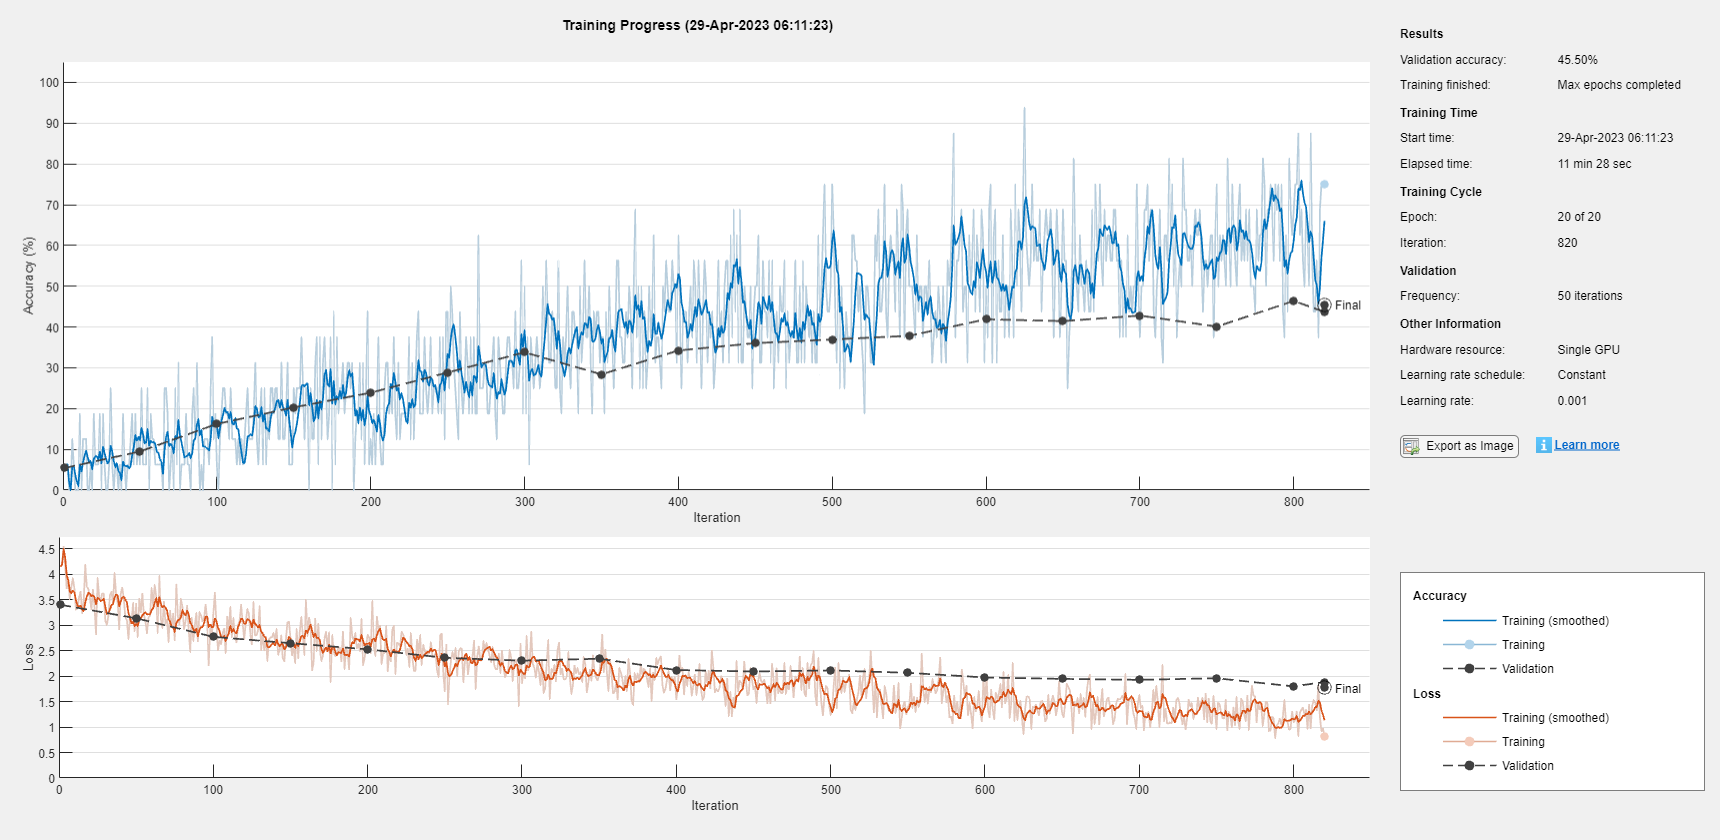

% learning_rate = 0.01;
learning_rate = 0.001;
% learning_rate = 0.0001;

% batch_size = 8;
batch_size = 16;
% batch_size = 32;

% epochs = 5;
% epochs = 10;
epochs = 20;

options = trainingOptions('sgdm', ...
        'InitialLearnRate', learning_rate, ...
        'MiniBatchSize', batch_size, ...
        'MaxEpochs', epochs, ...
        'Verbose', true, ...
        'Shuffle', 'every-epoch', ...
        'VerboseFrequency', 1, ...
        'ValidationData', validation_combined_datastore, ...
        'Plots','training-progress');

myCNN = trainNetwork(training_combined_datastore, layers, options);

target_predictions = classify(myCNN, test_image_datastore_resized);
target_test = testImageDS.Labels;

% Calculate overall accuracy
overall_accuracy = sum(target_predictions == target_test)/numel(target_test) % Output on command line

overall_accuracy = 0.4595

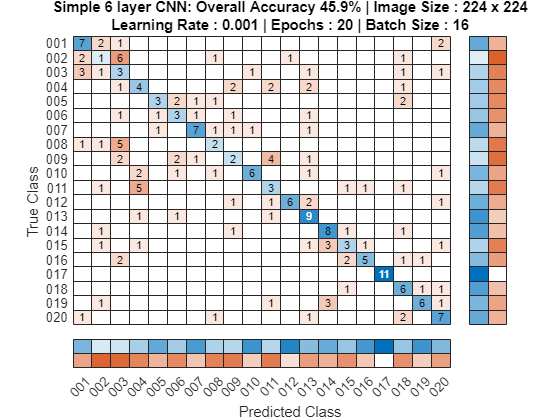


% Show confusion matrix in figure
[matrix, order] = confusionmat(target_test, target_predictions);
figure(2);
confusion_matrix = confusionchart(matrix, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title({"Simple 6 layer CNN: Overall Accuracy " + string(round(overall_accuracy*100, 1)) + "%" + ...
    " | Image Size : " + target_size(1) + " x " + target_size(1); ...
    "Learning Rate : " + learning_rate + " | Epochs : " + epochs + " | Batch Size : " + batch_size})


class_wise_correct_recognition_rates = zeros(height(order), 1);
samples_per_row = sum(matrix, 2);
for i = 1:height(order)
    class_wise_correct_recognition_rates(i) = round(100 * matrix(i, i) / samples_per_row(i), 1);
end
class_name_labels = table2array(classNames(:,2));

class_wise_recognition_rates = table(class_name_labels, ...
    class_wise_correct_recognition_rates, ...
    'VariableNames',["Class Name", "Correct Recognition Rate (%)"]);

disp("Class Weighted Average Overall Accuracy is " + string(round(overall_accuracy*100, 2)) + "%");

Class Weighted Average Overall Accuracy is 45.95%


disp(class_wise_recognition_rates);

              Class Name               Correct Recognition Rate (%)
    _______________________________    ____________________________

    {'001.Black_footed_Albatross' }                58.3            
    {'002.Laysan_Albatross'       }                 8.3            
    {'003.Sooty_Albatross'        }                27.3            
    {'004.Groove_billed_Ani'      }                33.3            
    {'005.Crested_Auklet'         }                33.3            
    {'006.Least_Auklet'           }                37.5            
    {'007.Parakeet_Auklet'        }                58.3            
    {'008.Rhinoceros_Auklet'      }                22.2            
    {'009.Brewer_Blackbird'       }                16.7            
    {'010.Red_winged_Blackbird'   }                  50            
    {'011.Rusty_Blackbird'        }                  25            
    {'012.Yellow_headed_Blackbird'}            